

clear all;

config = jsondecode(fileread('./config.json'));

addpath(config.paths.camera_directory);
addpath(config.paths.communication_directory);
% addpath('.\robot');

device = RobotUR3()

Establishing connection to UR3...
Connected to UR3.
Setup successful.


device =   RobotUR3 with properties:

         DEVICEIP: '192.168.1.1'
       DEVICEPORT: 30003
         MASTERIP: '172.20.10.5'
       MASTERPORT: 5000
        GRIPPERIP: ""
      GRIPPERPORT: 0
                a: 0.3000
                v: 0.5000
                t: 0
                r: 1.0000e-03
     deviceSocket: [1×1 tcpclient]
     masterSocket: []
    gripperSocket: []
             HOME: [0 -1.5708 0 -1.5708 -1.5708 0]
            state: []


ik = InverseKinematic()

ik =   InverseKinematic with properties:

             alpha: [6×1 double]
                 a: [6×1 double]
                 d: [6×1 double]
            thetas: [8×6 double]
    previousThetas: [0 0 0 0 0 0]
     currentThetas: [0 0 0 0 0 0]


camera = Camera3D(config.paths.camera_parameters)

ans =   cameraIntrinsics with properties:

             FocalLength: [925.9654 925.9056]
          PrincipalPoint: [641.6597 380.0837]
               ImageSize: [720 1280]
        RadialDistortion: [0.1506 -0.2320]
    TangentialDistortion: [0 0]
                    Skew: 0
                       K: [3×3 double]


Intel RealSense D435


camera =   Camera3D with properties:

       parameters: [1×1 cameraParameters]
             pipe: [1×1 realsense.pipeline]
    configuration: [1×1 realsense.config]
            align: [1×1 realsense.align]


detector = CupDetector(config.parameters.cup_detection_type)

detector =   CupDetector with properties:

         detector: []
    detectionMode: 'circle'




global processState;
processState = StateClass;

% establish connection to master via tcp/ip
% ip of master robot
% client = tcpclient('192.168.0.89',5000,"Timeout",50)
% local host
client = tcpclient('localhost',5000,"ConnectTimeout",30, "Timeout", 1)
% ip of test pc
% client = tcpclient('192.168.0.77',5000,"Timeout",50)
configureCallback(client, "byte", 1, @receiveDataFromConnection)

% test connection to master
recvData = read(client, 8, "uint8");
if recvData(1) == 1
    disp("control bit received, connection to master successful")
    com_data = [1,0,0,0,0,0,0,0];
    disp("send control bit")
    disp(com_data);
    send_com_data(client, com_data)
end

while true
%recvData = read(client, 8, "uint8")
%processState.state = recvData(2)
 if processState.state == 1 %&& state1done == false
     disp("State 1: Move to cup")
     state1done = true;
 elseif processState.state == 2 %&& state2done == false
     disp("state 2: close gripper")
     state2done = true;

 elseif processState.state == 3 %&& state3done == false 
     disp("state 3: pouring requested")
     state3done = true;

 elseif processState.state == 4 %&& state4done == false 
     disp("state 4: move back")
     state4done = true;

 elseif processState.state == 5 
     disp("state 5: task done!")

 else
     disp("something went wrong, or task is done")
 
 end
 pause(0.1);
end

% \\\\\\\\\\\\\\\\\\\\ 1 //////////////////// %
% calculate transformation matrix

% take a snapshot
image = imread(config.paths.calibration_image);

% calculate transformation from pcs to rcs
transform = TransformPCStoCCS(image, camera.parameters, config.parameters.edge_length);

ans = 1.0e+03 *

    1.0971    0.2243
    1.0738    0.1948
    1.0507    0.1652
    1.0275    0.1357
    1.0047    0.1060
    0.9818    0.0765
    1.0678    0.2469
    1.0443    0.2172
    1.0213    0.1876
    0.9979    0.1582


object =   TransformPCStoCCS with properties:

          dimensions: [6 7]
          edgeLength: 30
    cameraParameters: [1×1 cameraParameters]
          intrinsics: [1×1 cameraIntrinsics]
          extrinsics: []
    transformCCS2BCS: []
    transformBCS2RCS: []
           pointsPCS: [42×2 double]
           pointsBCS: [30×2 double]
           pointsCCS: [42×2 double]
           pointsRCS: []


Score: 100.63 %


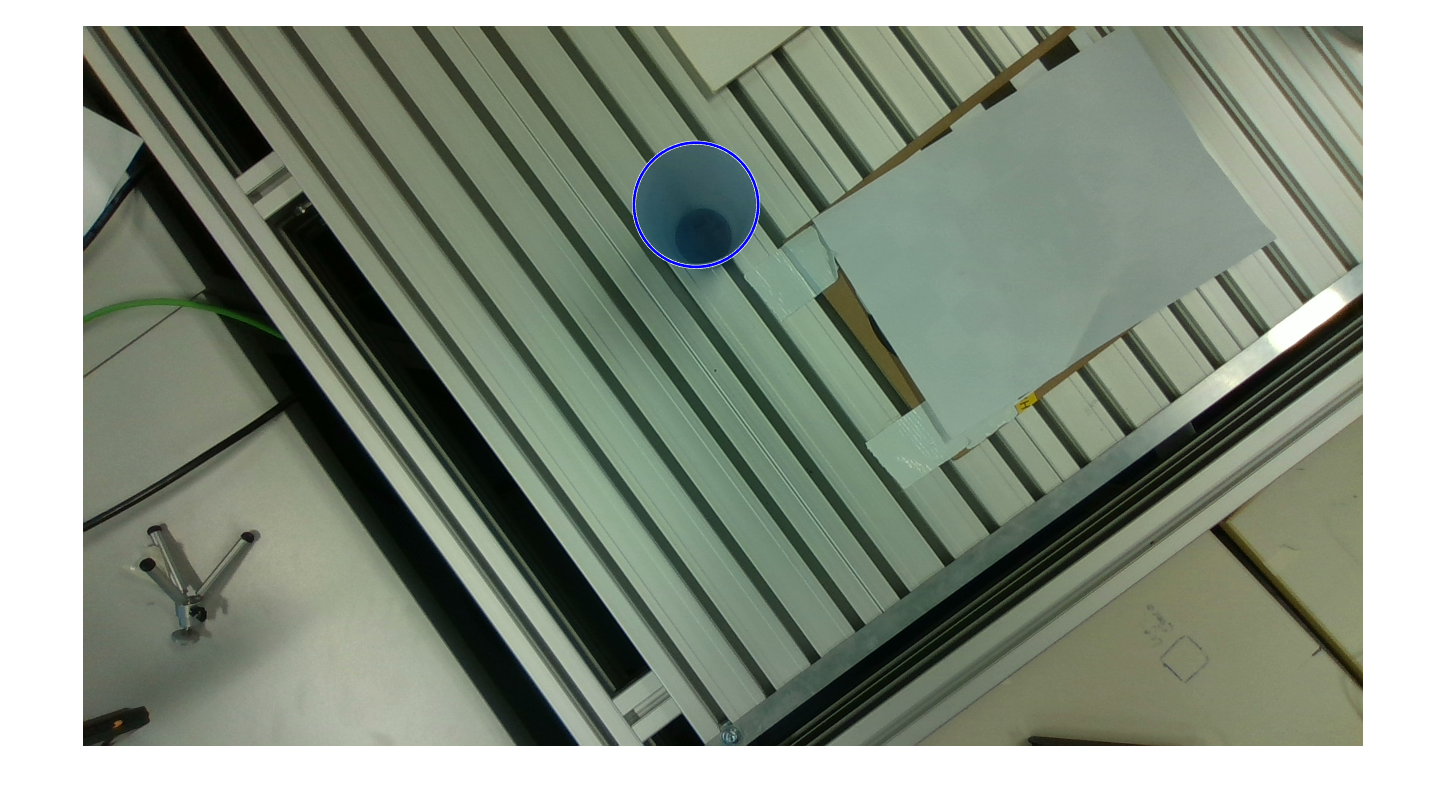

Cup detected


transform.extendToRCS(config.parameters.board_origin_rcs, config.parameters.board_corner_rcs);


% \\\\\\\\\\\\\\\\\\\\ 2 //////////////////// %
% detect cup and get its location

% take a snapshot
cupCenterPointPCS = camera.stream(@detector.detectCup);


% % receive cup location from detector
cupCenterPointPCS = cupCenterPointPCS(1:2);

% apply full transformation on the testing set
cupCenterPointRCS = transform.apply(cupCenterPointPCS);

targetPointsCCS =    22.4683  160.5551


targePointsBCS =   282.6978
  266.1311
         0
    1.0000



% remove augmentation
cupCenterPointRCS = cupCenterPointRCS(1:2)

cupCenterPointRCS =   594.8896 -175.7920



% add height to cup coordinates
% ACHTUNG KORREKTURWERT
cupCenterPointRCS(1) = cupCenterPointRCS(1) + config.parameters.cup_x_correction;
cupCenterPointRCS(2) = cupCenterPointRCS(2) + config.parameters.cup_y_correction;
cupCenterPointRCS(3) = config.parameters.cup_z_coordinate;

cupCenterPointRCS = cupCenterPointRCS / 1000;

% \\\\\\\\\\\\\\\\\\\\ 3 //////////////////// %
% move to cup location and grap cup

q = [0.0 -pi/2 -pi/2 -pi/2 -pi/2 0.0];
device.moveJ(q);
device.closeGripper();
device.openGripper();

testRot = [0.0, pi/2, 0.0]; % Rotationsvektor
ik.get_thetas(cupCenterPointRCS, testRot);
q = ik.currentThetas

q =    -0.1128   -2.3281   -1.3753   -2.5798   -1.6836   -1.5708


device.moveL(q)

pause

gripPos = cupCenterPointRCS;
gripPos(3) = config.parameters.final_grip_height;
ik.get_thetas(gripPos, testRot)
q = ik.currentThetas

q =     2.4040   -0.6018    1.4120   -0.8102    0.8332   -1.5708


device.moveL(q)
% device.moveL([cupCenterPointRCS(1), cupCenterPointRCS(2), cupCenterPointRCS(3), testRot(1), testRot(2), testRot(3)])

pause

gripPos = cupCenterPointRCS;
gripPos(3) = config.parameters.lift_grip_height;
ik.get_thetas(gripPos, testRot)
q = ik.currentThetas
device.moveL(q)

